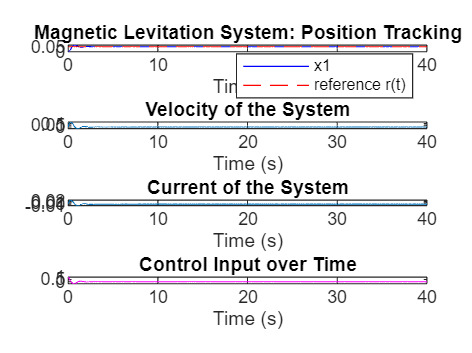

% a) Non Linear PID with y = 0.05
% Constants and Parameters
b = 0;          % Given constant
c = 1;          % Given constant
alpha = 1.5;    % Given constant
beta = 2;       % Given constant
T = @(x1) beta * (alpha + 1 / (1 + x1));  % Function T(x1) as described

% Reference Signal for Tracking
r = @(t) 0.05;     % Desired reference trajectory

% Nonlinear PID Gains (need tuning based on your system dynamics)
Kp = 2.15;      % Proportional gain (tuned down)
Ki = 18;        % Integral gain (tuned down)
Kd = 2.85;      % Derivative gain (tuned down)

% Simulation Parameters
tspan = [0, 40];                   % Simulation time span
x0 = [0; 0; 0];                    % Initial conditions [x1, x2, x3]
integral_error = 0;                % Initial integral error
max_integral = 1;                  % Limit for integral error

% Define a variable to store unique time and control input values
global control_input_time control_input_values;
control_input_time = [];           % Initialize time array for control input
control_input_values = [];         % Initialize array for control input values

% Define the ODE function with an additional output for control input
odefun = @(t, x) magnetic_levitation_dynamics1(t, x, r, Kp, Ki, Kd, integral_error, b, c, alpha, beta, max_integral);

% Simulate the System
[t, x] = ode45(@(t, x) odefun_wrapper(t, x, odefun), tspan, x0);

% Remove duplicate times and corresponding control input values
[control_input_time, unique_indices] = unique(control_input_time);
control_input_values = control_input_values(unique_indices);

% Interpolate control input values to match the time vector t
control_input_interp = interp1(control_input_time, control_input_values, t, 'previous', 'extrap');

% Plot Results
figure;
subplot(4, 1, 1);
plot(t, x(:, 1), 'b', t, arrayfun(r, t), 'r--');
xlabel('Time (s)');
ylabel('x1 (position)');
legend('x1', 'reference r(t)');
title('Magnetic Levitation System: Position Tracking');

subplot(4, 1, 2);
plot(t, x(:, 2));
xlabel('Time (s)');
ylabel('x2 (velocity)');
title('Velocity of the System');

subplot(4, 1, 3);
plot(t, x(:, 3));
xlabel('Time (s)');
ylabel('x3 (current)');
title('Current of the System');

subplot(4, 1, 4);
plot(t, control_input_interp, 'm');
xlabel('Time (s)');
ylabel('Control Input u');
title('Control Input over Time');


% Define the Dynamics Function
function [dx, u] = magnetic_levitation_dynamics1(t, x, r, Kp, Ki, Kd, integral_error, b, c, alpha, beta, max_integral)
    % State Variables
    x1 = x(1);  % Position
    x2 = x(2);  % Velocity
    x3 = x(3);
    
    % Reference and Tracking Error
    ref = r(t);
    error = ref - x1;
    integral_error = integral_error + error;  % Integrate the error
    
    % Saturate the integral error
    integral_error = max(min(integral_error, max_integral), -max_integral);
    
    % PID Control Law (Nonlinear)
    u = Kp * error + Ki * integral_error - Kd * x2;
    
    % Apply damping to the control input
    u = max(min(u, 1), -1);  % Limit the control input to avoid extreme values
    
    % Dynamics based on given equations
    dx1 = x2;
    dx2 = -b * x2 + c * u - 0.1 * x2;  % Include damping term
    dx3 = (1 / (beta * (alpha + 1 / (1 + x1)))) * (-x3 + u + (beta * x2 * x3) / (1 + x1)^2);

    % Collect Derivatives
    dx = [dx1; dx2; dx3];
end

% Wrapper function to capture unique control input at each time step
function dx = odefun_wrapper(t, x, odefun)
    global control_input_time control_input_values;
    [dx, u] = odefun(t, x);
    
    % Only store if the time step is unique
    if isempty(control_input_time) || t > control_input_time(end)
        control_input_time(end + 1) = t;          % Store unique time of control input
        control_input_values(end + 1) = u;        % Store corresponding control input value
    end
end



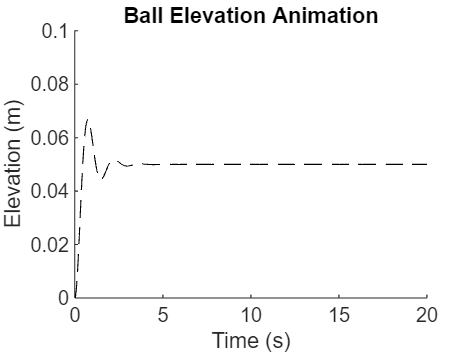


% Animation Setup
figure;
hold on;
xlabel('Time (s)');
ylabel('Elevation (m)');
title('Ball Elevation Animation');
ylim([0, 0.1]);         % Set vertical limits for ball position
xlim([0, 20]);    % Set horizontal limits for animation view
ball = plot(0, x0(1), 'o', 'MarkerSize', 20, 'MarkerFaceColor', 'b');  % Ball plot
ball_path = plot(0, x0(1), 'k--');  % Path of the ball (horizontal)

% Animation Loop (Horizontal and Vertical Movement)
for i = 1:length(t)
    % Update Ball Position
    set(ball, 'YData', x(i, 1));  % Update the ball's vertical position (x1)
    set(ball, 'XData', t(i));     % Update the ball's horizontal position (t)
    
    % Update the ball path (trace of horizontal position)
    set(ball_path, 'XData', t(1:i));  % Update the horizontal position path
    set(ball_path, 'YData', x(1:i, 1));  % Update the vertical position along the path
    
    % Pause to control animation speed (based on simulation time step)
    pause(0.01);
end

hold off;

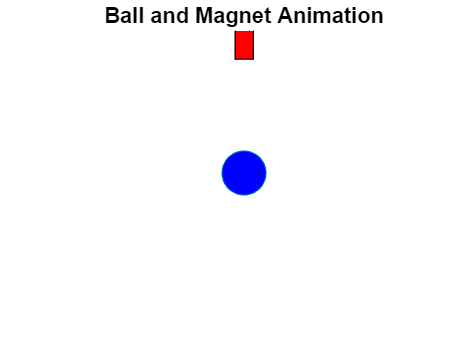



%meglev Demo

figure;
hold on;
title('Ball and Magnet Animation');
ylim([0, 0.1]);  % Set vertical limits for ball position (adjust as needed)
xlim([-0.2, 0.2]);  % Set horizontal limits (magnet and ball don't move horizontally)

% Initializing Ball (Blue Circle) - Positioned to the right of the magnet
ball = plot(0, x0(1), 'o', 'MarkerSize', 20, 'MarkerFaceColor', 'b');  

% Initializing Magnet (Red Rectangle) - Positioned below the ball on the Y-axis
magnet = rectangle('Position', [-0.01, 0.09, 0.02, 0.05], 'FaceColor', 'r');  % Magnet stays fixed below the ball

% Adjust the figure to make sure the magnet and ball appear
axis off; % Turn off the axis display
hold on;
% Animation Loop (Ball Moving Vertically)
for i = 1:length(t)
    % Update Ball Position (Ball on the right, vertical movement)
    set(ball, 'YData', x(i, 1));  % Update the ball's vertical position (x1)
    
     pause(0.01);
end

hold off;